**180237G**

**S.S.Hettiarachchi**

**BME**

## **MATLAB EXERCISE 4**

We can use MATLAB to calculate characteristics of a second order system, such as damping ratio, $\zeta$; natural frequency, $\omega_n$; percent overshoot, %OS (pos); settling time,$T_s$ ; and peak time,$T_p$. Observe the MATLAB code below for the calculation of above parameters for the following pole-zero plot.

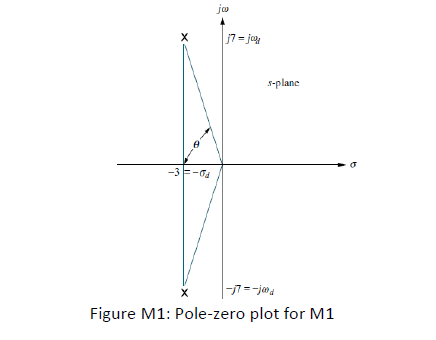

p1=[1 3+7*1j]; % Define polynomial containing first pole.
p2=[1 3-7*1j]; % Define polynomial containing second pole.
den=conv(p1 ,p2); % Multiply the two polynomials to find the 2nd order % polynomial, as^2+bs+c.
omegan=sqrt (den (3) /den (1)) ;% Calculate the natural frequency, sqrt(c/a).
zeta=(den(2)/den(1))/(2*omegan); % Calculate damping ratio, ((b/a)/2*wn).
Ts=4/(zeta*omegan); % Calculate settling time, (4/z*wn).
Tp=pi/(omegan*sqrt(1-zeta^2)); % Calculate peak time, pi/wn*sqrt(l -z^2).
pos=100*exp( -zeta*pi/sqrt(1-zeta^2)); % Calculate percent overshoot (100*e^(-z*pi/sqrt(l-% z^2)).

fprintf('Damping ratio(ζ)= %f.\n',zeta);

Damping ratio(ζ)= 0.393919.


fprintf('Natural frequence= %f.\n',omegan);

Natural frequence= 7.615773.


fprintf('Precentage overshoot(%OS)= %f.\n',pos);

Precentage overshoot(

fprintf('Settling Time(Ts)= %f.\n',Ts);

Settling Time(Ts)= 1.333333.


fprintf('Peak Time(Ts)= %f.\n',Tp);

Peak Time(Ts)= 0.448799.


Use the above procedure to find $\zeta$, $\omega_n$, %OS, $T_s$ and $T_p$ for the following second order system.


$$G\left(S\right)=\frac{10}{3S^2 +8S+24}$$



$$G\left(S\right)=\frac{\left(\frac{10}{3}\right)}{S^2 +\left(\frac{8}{3}\right)S+8}$$



$$\mathrm{poles}\;\;\;\;\;S=-1\ldotp 33\pm 2\ldotp 494$$
 

p1=[1 1.33+2.494*1j]; % Define polynomial containing first pole.
p2=[1 1.33-2.494*1j]; % Define polynomial containing second pole.
den=conv(p1 ,p2); % Multiply the two polynomials to find the 2nd order % polynomial, as^2+bs+c.
omegan=sqrt (den (3) /den (1)); % Calculate the natural frequency, sqrt(c/a).
zeta=(den(2)/den(1))/(2*omegan); % Calculate damping ratio, ((b/a)/2*wn).
Ts=4/(zeta*omegan) % Calculate settling time, (4/z*wn).

Ts = 3.0075

Tp=pi/(omegan*sqrt(1-zeta^2)); % Calculate peak time, pi/wn*sqrt(l -z^2).
pos=100*exp(-zeta*pi/sqrt(1-zeta^2)); % Calculate percent overshoot (100*e^(-z*pi/sqrt(l-% z^2)).

fprintf('Damping ratio(ζ)= %f.\n',zeta);

Damping ratio(ζ)= 0.470552.


fprintf('Natural frequence= %f.\n',omegan);

Natural frequence= 2.826471.


fprintf('Precentage overshoot(%%OS)= %f.\n',pos);

Precentage overshoot(%OS)= 18.724298.


fprintf('Settling Time(Ts)= %f.\n',Ts);

Settling Time(Ts)= 3.007519.


fprintf('Peak Time(Ts)= %f.\n',Tp);

Peak Time(Ts)= 1.259660.


Use tf and stepplot or step functions to plot the step response, and compare with the results obtained before. Note: You may left click the mouse on the curve to get more information about a particular coordinate. Moreover, by right clicking away from the curve brings up a menu, from which you can obtain the characteristics of the step response curve by mouse pointing at the appearing dots.

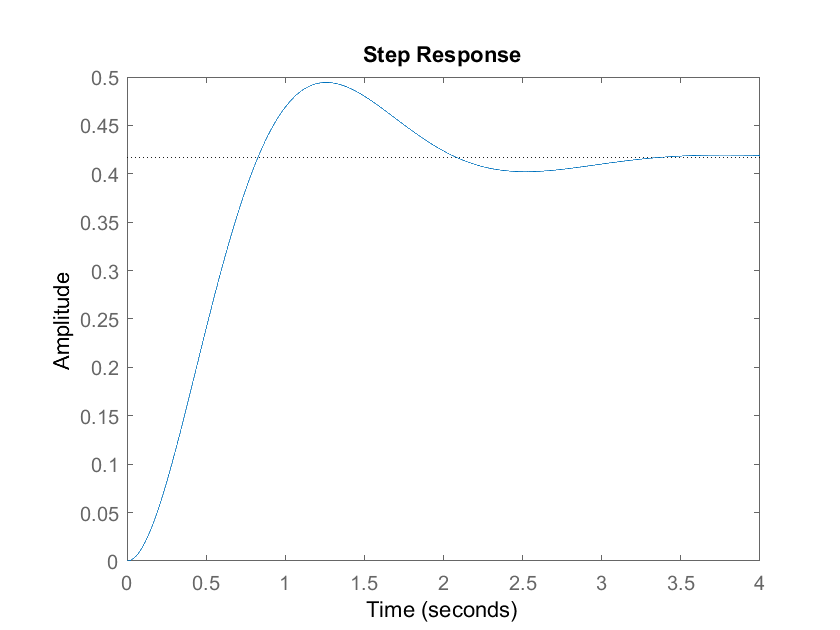

num=10;
deno=[3 8 24];
H=tf(num,deno);
stepplot(H,0:0.001:4);


$$\begin{array}{l}
T_p =1\ldotp 263s\\
Y_{\textrm{peak}} =0\ldotp 4944\\
Y_{\mathrm{final}} =0\ldotp 4169
\end{array}$$



$$\begin{array}{l}
t_1 =0\ldotp 172\;<-------\;\;Y=0\ldotp 1\times 0\ldotp 4169=0\ldotp 04169\\
t_1 =0\ldotp 732\;<-------\;\;Y=0\ldotp 9\times 0\ldotp 4169=0\ldotp 37521\\
t_2 -t_2 =0\ldotp 732-0\ldotp 172=0\ldotp 56s\\
\textrm{Therefore}\;\;\;T_r =0\ldotp 56
\end{array}$$


-------------------------------------------------------------------------------------------------------

$T_s =$2.931s $<-------\;\;Y=0\ldotp 98\times 0\ldotp 4169=0\ldotp 4085$

-------------------------------------------------------------------------------------------------------


$$%\mathrm{OS}=\frac{C_{\mathrm{max}} -C_{\mathrm{final}} }{C_{\mathrm{final}} }\times 100%=\frac{\left(0\ldotp 4944-0\ldotp 4169\right)}{0\ldotp 4169}\times 100%=18\ldotp 58%$$


Therfore calculated results are nearly equals to results from graphs.

2. For a 2nd order system, obtain the following response curves by changing$\;\zeta$� from 0.2 to 2.

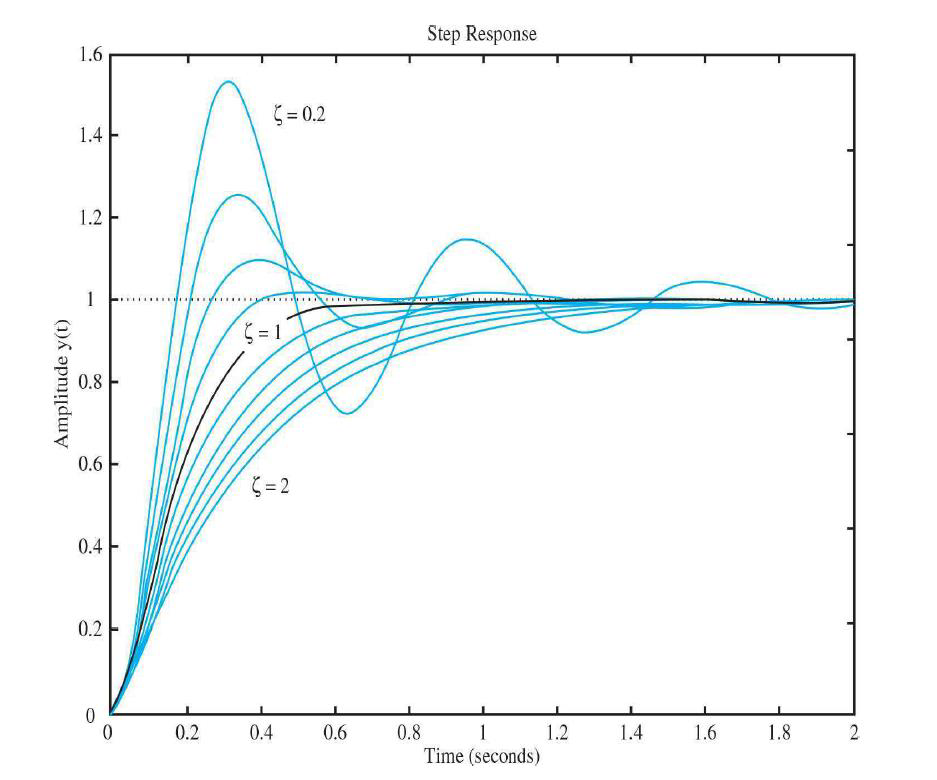


$$T_p =0\ldotp 3s$$



$$\begin{array}{l}
T_p =\frac{\pi }{\omega_n \sqrt{1-\zeta^2 }}----->\omega_n =10\ldotp 688\\
\omega_n^2 =114\ldotp 23\\
T\left(S\right)=\frac{\omega_n^2 }{S^2 +a\omega_n S+\omega_n^2 }\;\;\;\;\;a=2\zeta 
\end{array}$$


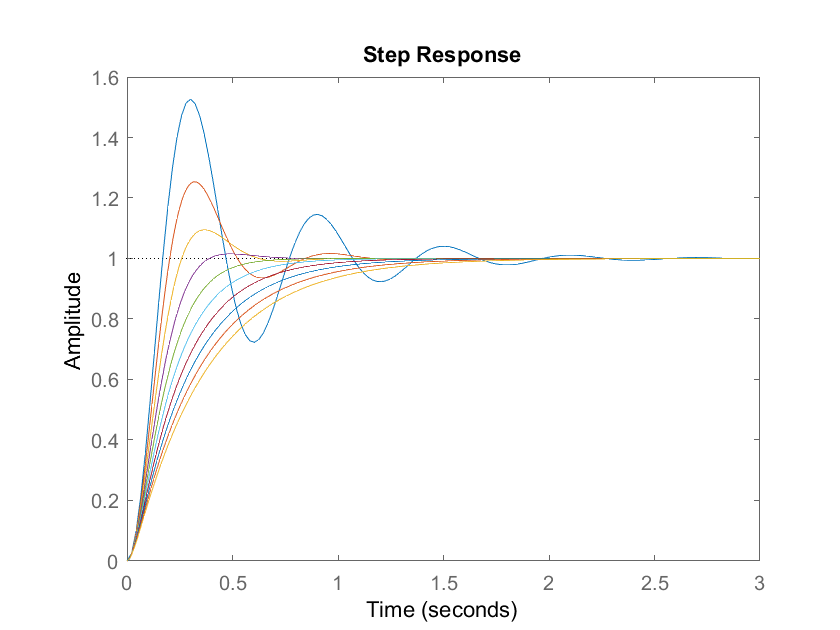

num=114.23;
omega=10.688;
H1=tf(num,[1 2*omega*0.2 114.23]);
H2=tf(num,[1 2*omega*0.4 114.23]);
H3=tf(num,[1 2*omega*0.6 114.23]);
H4=tf(num,[1 2*omega*0.8 114.23]);
H5=tf(num,[1 2*omega*1.0 114.23]);
H6=tf(num,[1 2*omega*1.2 114.23]);
H7=tf(num,[1 2*omega*1.4 114.23]);
H8=tf(num,[1 2*omega*1.6 114.23]);
H9=tf(num,[1 2*omega*1.8 114.23]);
H10=tf(num,[1 2*omega*2.0 114.23]);

stepplot(H1,H2,H3,H4,H5,H6,H7,H8,H9,H10)

3. For a 2nd order system, figure out what happens to %OS when $\zeta$ changes from 0 to 1 (slide #42). Plot the result.

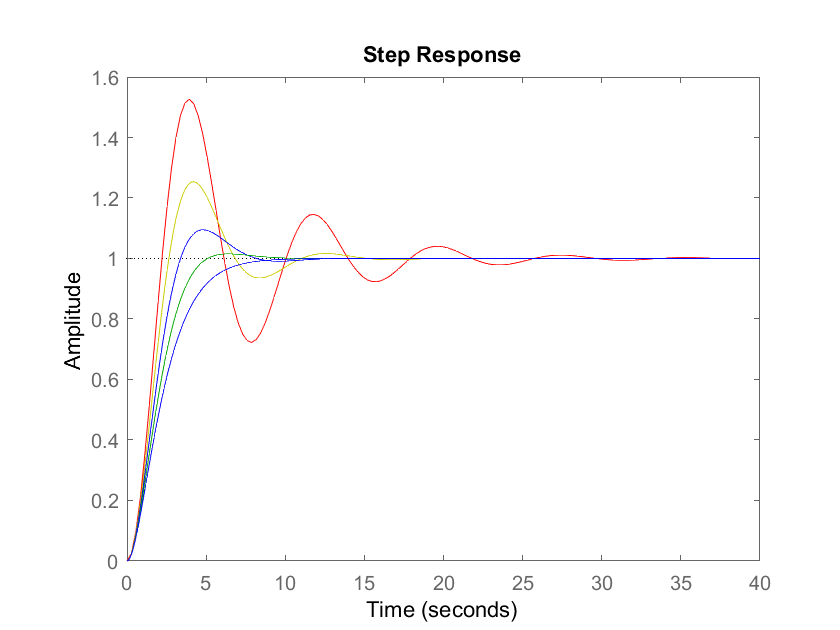

num=0.669;
omega=0.818;

H2=tf(num,[1 2*omega*0.2 0.669]);
H3=tf(num,[1 2*omega*0.4 0.669]);
H4=tf(num,[1 2*omega*0.6 0.669]);
H5=tf(num,[1 2*omega*0.8 0.669]);
H6=tf(num,[1 2*omega*1.0 0.669]);


stepplot(H2,'r',H3,'y',H4,'b',H5,'g',H6,'bl');

When $\zeta \;$is increasing, $C_{\mathrm{max}\;}$ is decreasing but $C_{\mathrm{final}\;}$is constant. Therfore %OS is decreasing.